clc
clear all
close all
addpath('functions/');

cvx_clear
cvx_solver sedumi
cvx_precision best

## Initialize system benchmark model

load('Benchmark_model.mat')
% Parameters to be tuned
h = 0.1;                    % Sampling time [s]
v = 2;                      % Bicycle velocity [m/s]
N = 8;                      % Control horizon [-]
steps = 60;                 

% initialize states
phi_0 =  10 * pi/180;        % Initial roll angle in radians
delta_0 = 0 * pi/180;       % Initial steering angle in radians
phi_dot_0 = 10 * pi/180;    % Initial roll angle speed in radians/s
delta_dot_0 = 0 * pi/180;   % Initial steering angle speed in radians/s

% Weighting matrices
Q = 1*eye(4);          % Weighting matrix for states
R = 1*eye(2);          % Weighting matrix for the inputs


## Discretize system

[bic_sys, matrices] = Bicycle_model(v);
check_controllability(bic_sys);

rnk = 4

sysd = c2d(bic_sys,h,'ZOH');

% LTI
LTI.A = sysd.A;
LTI.B = sysd.B;
LTI.C = sysd.C;

A = sysd.A;
B = sysd.B;
C = sysd.C;

% Dimensions
dim.nx = size(A,1);
dim.nu = size(B,2);
dim.N = N;


## MPC regulator


% simulaton time
T = steps*h;
t_time(1) = 0;

% Initialize matrices for speed
x = zeros(length(A),steps+1);
u = zeros(size(B,2),steps);
y = zeros(size(C,1),steps);

x0 = [phi_0; delta_0; phi_dot_0 ; delta_dot_0];          % Initial state
LTI.x0 = x0;
x(:,1) = x0;

weight.Q = Q;
weight.R = R;

% Terminal cost
[P,K_LQR,~] = idare(A,B,Q,R);         % Solving the DARE to find the optimal terminal weighting matrix
weight.P = P;
check_posdef(P)

Positive definite



% Prediction matrices
predmod = predmodgen(LTI,dim);

% Cost matrices
[H,F_x0less] = optimatrix(predmod,dim,weight);

% State constraints 
F_constr = kron(eye(dim.nx),[1; -1]);    
phi_max = pi/3;
e_state = phi_max*[0.5; 0.5; 0.5; 0.5; 0.42; 0.42; 0.84; 0.84];

x_const_set = constraintmaker(dim.N,F_constr,e_state);

% input constraints
E_constr = kron(eye(dim.nu),[1; -1])

E_constr =      1     0
    -1     0
     0     1
     0    -1


max_lean_moment = 40/29.2*(m_rf+m_ff+m_fw+m_rw);
max_steer_torque = 5;
e_input = [max_lean_moment; max_lean_moment; max_steer_torque; max_steer_torque];

u_const_set = constraintmaker(dim.N,E_constr,e_input);

constraint.F = F_constr;
constraint.es = e_state;
constraint.E = E_constr;
constraint.ei = e_input;

A_ots = blkdiag(E_constr,F_constr);
b_ots = [e_state;e_input];


## Xf invariant set calc

A_LQR = A - B*K_LQR;
C_xf = [K_LQR; eye(dim.nx)];
s = size(A_ots,1);
[Xf_set_H, Xf_set_h, kstar] = calcInvariantXf(A_LQR,C_xf,A_ots,b_ots,s,dim);


for i = 1:steps
    
    t_time(i+1) = t_time(i) + h;
    x0 = x(:,i);
    F = x0'*F_x0less;
    
    cvx_begin quiet
        variable u_pred(dim.nu*dim.N)
        minimize ( (1/2)*quad_form(u_pred,H) + F*u_pred )
    
        % input constraints
        u_const_set.E*u_pred <= u_const_set.e
    
        % state constraints
        x_const_set.E*(predmod.T(dim.nx+1:end,:)*x0 + predmod.S(dim.nx+1:end,:)*u_pred) <= x_const_set.e
    
        % Terminal constraint
        Xf_set_H*(predmod.T(end-dim.nx+1:end,:)*x0 + predmod.S(end-dim.nx+1:end,:)*u_pred ) <= Xf_set_h;
      
    cvx_end
    
    u_store(:,i) = u_pred;
    u(:,i) = u_pred(1:2,1);
    
    x(:,i+1) = A*x(:,i) + B*u(:,i);
    y(:,i) = C*x(:,i);
    
end


## Plot

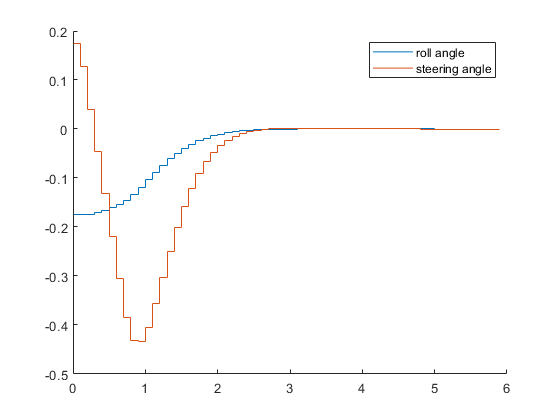

figure(1)
hold on
stairs(t_time(1,1:end-1),y(1,:))
stairs(t_time(1,1:end-1),y(2,:))
legend 'roll angle' 'steering angle'
hold off

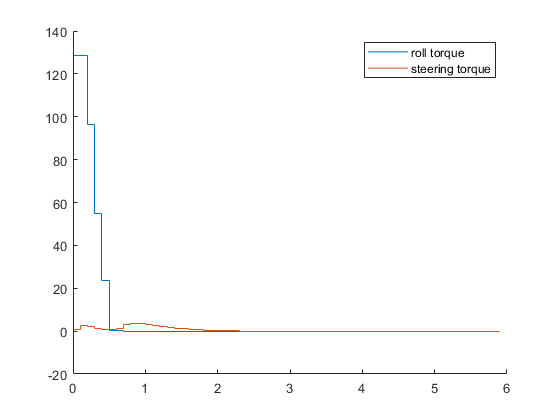


figure(2)
hold on
stairs(t_time(1,1:end-1),u(1,:))
stairs(t_time(1,1:end-1),u(2,:))
legend 'roll torque' 'steering torque'
hold off